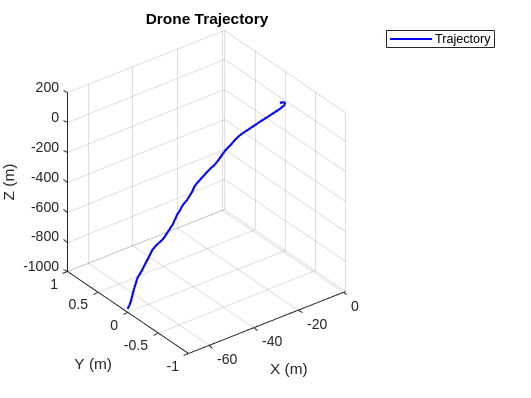

clc;
clear variables;
close all;


 % [x y z vx vy vz phi theta psi p q r]
% System params
m = 1.535;
g = 9.81;
Ixx = 0.029125;
Iyy = 0.029125;
Izz = 0.055225;
kt = 0.0;
kr = 0.0;

%Time variables
t_final = 15;
t_interval = 0.1;

time_span = 0:t_interval:t_final;

%State variables
state_all=[];
t_all=[];
current_state = zeros(1, 12);

%control input
u = [0; 0.0; 0.0; 0.0];
% n_steps = length(time);
% init_val_M = zeros(n_steps, 12);

%Set position values
x_ref = 7; y_ref = 3; z_ref = 5; 
yaw_ref = 0; 


Ts_phi=0.1;
kd_phi=8*Iyy/Ts_phi;
kp_phi=(kd_phi*kd_phi)/(4*Ixx*3*3);
ki_phi=0.0;

Ts_theta=0.1;
kd_theta=8*Iyy/Ts_theta;
kp_theta=(kd_theta*kd_theta)/(4*Iyy*3*3);
ki_theta=0.0;

Ts_psi=0.1;
kd_psi=8*Izz/Ts_psi;
kp_psi=(kd_psi*kd_psi)/(4*Izz);
ki_psi=0.0;

% PID GAINS for Velocity Controller

Ts_z_dot= 1;
kd_z_dot=0.465;
kp_z_dot= 4*(m+kd_z_dot)/Ts_z_dot;
ki_z_dot=0.0;

Ts_x_dot= 1.0;
kd_x_dot= 0.01;
kp_x_dot= (1.0981*4)/(9.81*Ts_x_dot);
ki_x_dot=0.0;

Ts_y_dot= 1.0;
kd_y_dot= 0.01;
kp_y_dot= (1.0981*4)/(9.81*Ts_y_dot);
ki_y_dot=0.0;

%P Controller gains for positions
kp_x=;
kp_y=0.0;
kp_z=0.4;

%Temp variables
error_prev_z_dot=0.0;
error_prev_z_dot_in=0.0;

error_prev_x_dot=0.0;
error_prev_x_dot_in=0.0;

error_prev_y_dot=0.0;
error_prev_y_dot_in=0.0;

error_prev_theta=0.0;
error_prev_theta_in=0.0;

error_prev_phi=0.0;
error_prev_phi_in=0.0;

error_prev_psi=0.0;
error_prev_psi_in=0.0;

for idx = 1:length(time_span)-1
    t_now = [time_span(idx), time_span(idx+1)];

    % State unpack
    x = current_state(1); y = current_state(2); z = current_state(3);
    vx = current_state(4); vy = current_state(5); vz = current_state(6);
    phi = current_state(7); theta = current_state(8); psi = current_state(9);
    p = current_state(10); q = current_state(11); r = current_state(12);

    %% --- PID for Position Control ---
    pos = [x; y; z];
    vel = [vx; vy; vz];
    ref_pos = [x_ref; y_ref; z_ref];

    % P CONTROL for position
    z_dot_d = kp_z * (z_ref - z);  
    % z_dot_d = min(15, z_dot_d);  % Limit the desired z velocity

    % PID CONTROL for z velocity (inline implementation)    
    error_z_dot = z_dot_d - vz;
    derivative_z_dot = (error_z_dot - error_prev_z_dot);
    integral_z_dot = error_prev_z_dot_in + error_z_dot;

    u(1) = kp_z_dot * error_z_dot + kd_z_dot * derivative_z_dot + ki_z_dot * integral_z_dot;
    u(1) = u(1) + m * g;  % Add gravity compensation

    % Update previous error values for next iteration
    error_prev_z_dot = error_z_dot;
    error_prev_z_dot_in = integral_z_dot;












%     Attitude theta
% 
% P CONTROL for x position
x_dot_d = kp_x * (x_ref - x);
x_dot_d = min(8.5, x_dot_d);

%PID CONTROL for x velocity
error_x_dot = x_dot_d - vx;
%derivative_x_dot = (error_x_dot - error_prev_x_dot) / dt;
derivative_x_dot = (error_x_dot - error_prev_x_dot);
error_prev_x_dot_in = error_prev_x_dot_in + error_x_dot;
theta_d = kp_x_dot * error_x_dot + kd_x_dot * derivative_x_dot + ki_x_dot * error_prev_x_dot_in;
error_prev_x_dot = error_x_dot;

if (theta_d > 0.0)
    theta_d = min(0.17, theta_d);
end
if (theta_d < 0.0)
    theta_d = max(-0.17, theta_d);
end

error_theta = theta_d - theta;
%derivative_theta = (error_theta - error_prev_theta) / dt;
derivative_theta = (error_theta - error_prev_theta);
error_prev_theta_in = error_prev_theta_in + error_theta;
u(3) = kp_theta * error_theta + kd_theta * derivative_theta + ki_theta * error_prev_theta_in;
error_prev_theta = error_theta;


%Attitude phi

%P CONTROL for y position
y_dot_d = kp_y * (y_ref - y);
y_dot_d = min(8.5, y_dot_d);

%PID CONTROL for y velocity
error_y_dot = y_dot_d - vy;
derivative_y_dot = (error_y_dot - error_prev_y_dot);
error_prev_y_dot_in = error_prev_y_dot_in + error_y_dot;
phi_d = kp_y_dot * error_y_dot + kd_y_dot * derivative_y_dot + ki_y_dot * error_prev_y_dot_in;
error_prev_y_dot = error_y_dot;

if (phi_d > 0.0)
    phi_d = min(0.17, phi_d);
end
if (phi_d < 0.0)
    phi_d = max(-0.17, phi_d);
end

error_phi = -phi_d - phi;
derivative_phi = (error_phi - error_prev_phi);
error_prev_phi_in = error_prev_phi_in + error_phi;
u(2) = kp_phi * error_phi + kd_phi * derivative_phi + ki_phi * error_prev_phi_in;
error_prev_phi = error_phi;


% Attitude yaw PID control
error_psi = 0.0 - psi;
derivative_psi = (error_psi - error_prev_psi);
error_prev_psi_in = error_prev_psi_in + error_psi;
u(4) = kp_psi * error_psi + kd_psi * derivative_psi + ki_psi * error_prev_psi_in;
error_prev_psi = error_psi;

    %u=[1.535*9.81,0.0,0.0,0.0];
    u=[u(1),u(2),u(3),u(4)];

    % Integrate dynamics
    [t, y_] = ode45(@(t, y) droneDynamics(t, y, u, m, g, Ixx, Iyy, Izz, kt, kr), t_now, current_state);
    state_all = [state_all; y_(1:end-1, :)]; % Exclude the last point to avoid duplication
    t_all = [t_all; t(1:end-1)];
    current_state = y_(end, :)';

end
% state_all = [state_all; current_state'];
% t_all = [t_all; tspan(end)];

%Plotting
figure;
plot3(state_all(:, 1), state_all(:, 2), state_all(:, 3), 'b', 'LineWidth', 1.5);
grid on;
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('Drone Trajectory');
legend('Trajectory');

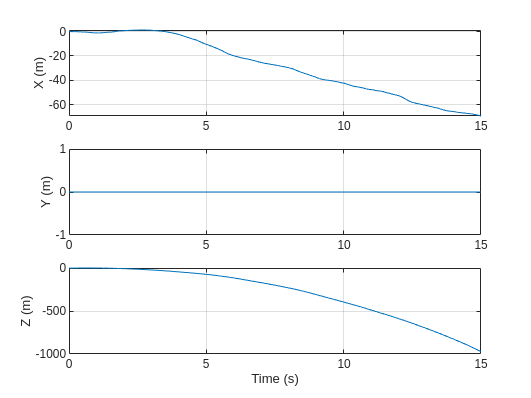


% figure;
% plot3(init_val_M(:,1), init_val_M(:,2), init_val_M(:,3), 'b', 'LineWidth', 1);
% xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
% title('3D Drone Trajectory (Full PID Control)');
% grid on; axis equal;
% 
% figure;
subplot(3,1,1); plot(t_all, state_all(:,1)); ylabel('X (m)'); grid on;
subplot(3,1,2); plot(t_all, state_all(:,2)); ylabel('Y (m)'); grid on;
subplot(3,1,3); plot(t_all, state_all(:,3)); ylabel('Z (m)'); xlabel('Time (s)'); grid on;

function dydt = droneDynamics(t, y, u,m,g,Ixx,Iyy,Izz,kt,kr)

    % State variables
    x_pos = y(1); y_pos = y(2); z_pos = y(3); % position
    vx = y(4); vy = y(5); vz = y(6); % velocity
    phi = y(7); theta = y(8); psi = y(9); % orientation
    p = y(10); q = y(11); r = y(12); % angular velocity

    T = u(1); % total thrust


    % Translational dynamics
    acc=[(1/(m))*((cos(phi)*cos(psi)*sin(theta)+sin(phi)*sin(psi))*T -kt*vx);
         (1/(m))*((cos(phi)*sin(psi)*sin(theta)-cos(psi)*sin(phi))*T -kt*vy) ;
         (1/(m))*((cos(phi)*cos(theta))*T - m*g - kt*vz)];
    
    % Rotational Dynamics
    ang_acc =[(1/Ixx)*(-kr*p -q*r*( Izz - Iyy)+u(2)) ;
              (1/Iyy)*(-kr*q-p*r*( Ixx - Izz)+u(3));
              (1/Izz)*(-kr*r-p*q*( Iyy - Ixx)+u(4))];

    % Derivatives
    dydt = zeros(12, 1);
    dydt(1:3) = [vx; vy; vz]; % position derivatives
    dydt(4:6) = acc;          % velocity derivatives
    dydt(7:9) = [p+(q*sin(phi)*tan(theta))+(r*cos(phi)*tan(theta));(q*cos(phi))-(r*sin(phi));(1/cos(theta))*(q*sin(phi)+r*cos(phi))]; % orientation derivatives
    dydt(10:12) = ang_acc; % angular velocity derivatives
end


